clc;
clear;
close all;


正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 8 个工作进程的并行池。


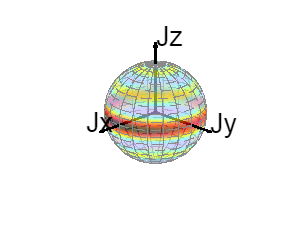

% Example1: For an arbitrary input state vector or density matrix

state = [[1.10635674e-10]
 [5.69368449e-08]
 [1.39820063e-05]
 [1.67372366e-03]
 [8.25903465e-02]
 [9.93152590e-01]
 [8.25903465e-02]
 [1.67372366e-03]
 [1.39820063e-05]
 [5.69368449e-08]
 [1.10635674e-10]];

[Q,figQ] = bloch(state);
[W,figW] = bloch(state,"Wigner");


% [dis, h] = bloch(state, distribution, views)
% distribution: "Husimi"(default)  or "Wigner"
% views: "X", "Y", "Z",  plot the 3D views when 

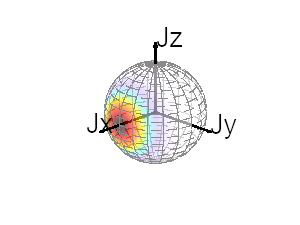

% Example2: spin coherent state 

N = 10;
sys = CollectiveSpin(N);
theta_SCS = pi/2;
phi_SCS = 0;
SCS = sys.SCS(theta_SCS,phi_SCS);
[Q1,figQ1] = bloch(SCS,"Husimi");

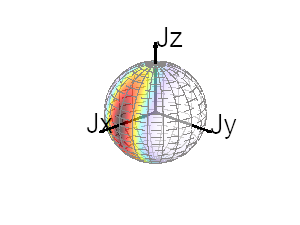


% Example3: spin squeezed state 

% chit = 24^(1/6)*(N/2)^(-2/3); 
chit = 0.5*24^(1/6)*(N/2)^(-2/3);
% SSS = sys.Rx(pi/2+sys.phi_OAT_opt(chit))*sys.OAT(chit,"z")*SCS; %
SSS = sys.SSS_opt(chit);

[Q2,figQ2] = bloch(SSS,"Husimi");